# Experiment 3_3 

### Group members: 

Arman Miraghasi Khani - 40023080

Tina Shariatzadeh - 40023043

Parsa Salehi - 40023048

### clear workspace

clc;
clear;
close all;

### Part 1: Level Detector

fs = 1e3;
t = 0:1 / fs:1;
f0 = 10;
A = 2;
x = A * cos(2 * pi * f0 * t);

a) rms

ms_val_x = mean(x .^ 2);
disp(ms_val_x);

    2.0020



disp(A ^ 2/2);

     2



b) mean abs

mean_abs_x = mean(abs(x));
disp(mean_abs_x);

    1.2735



disp(2 * A / pi);

    1.2732



### Part 2: Dynamic Processors 

#### a) Compressor

Input signal

w0 = pi * 0.15;
n = [0:199; 200:399; 400:599];
A = [2 4 0.5];
x = cos(w0 * n) .* A';
x = x';
x = x(1:end);
n = n';
n = n(1:end);

Control Signal

lambda = 0.9;
c0 = 0.5;
rho = 0.2;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

Gain Signal

gn     = ones(size(cn));
above  = cn >= c0;
gn(above) = (cn(above) / c0).^(rho - 1);
yn_compressor = gn .* x;

Plot Signals

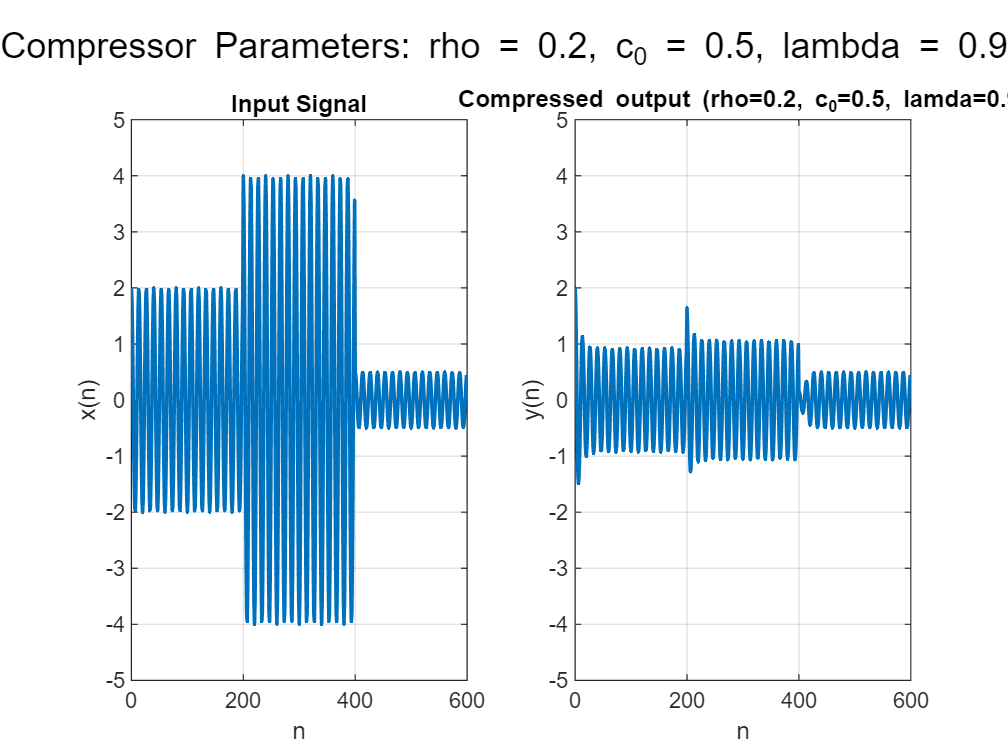

figure("Name", 'Input Signal vs Compressed Signal');
sgtitle('Compressor Parameters: rho = 0.2, c_0 = 0.5, lambda = 0.9');
subplot(1, 2, 1);
plot(n, x, 'LineWidth', 1.5);
title('Input Signal');
xlabel('n');
ylabel('x(n)');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, yn_compressor, 'LineWidth', 1.5);
title('Compressed output (rho=0.2, c_0=0.5, lamda=0.9)');
xlabel('n');
ylabel('y(n)');
xlim([0 600]);
ylim([-5 5]);
grid on;

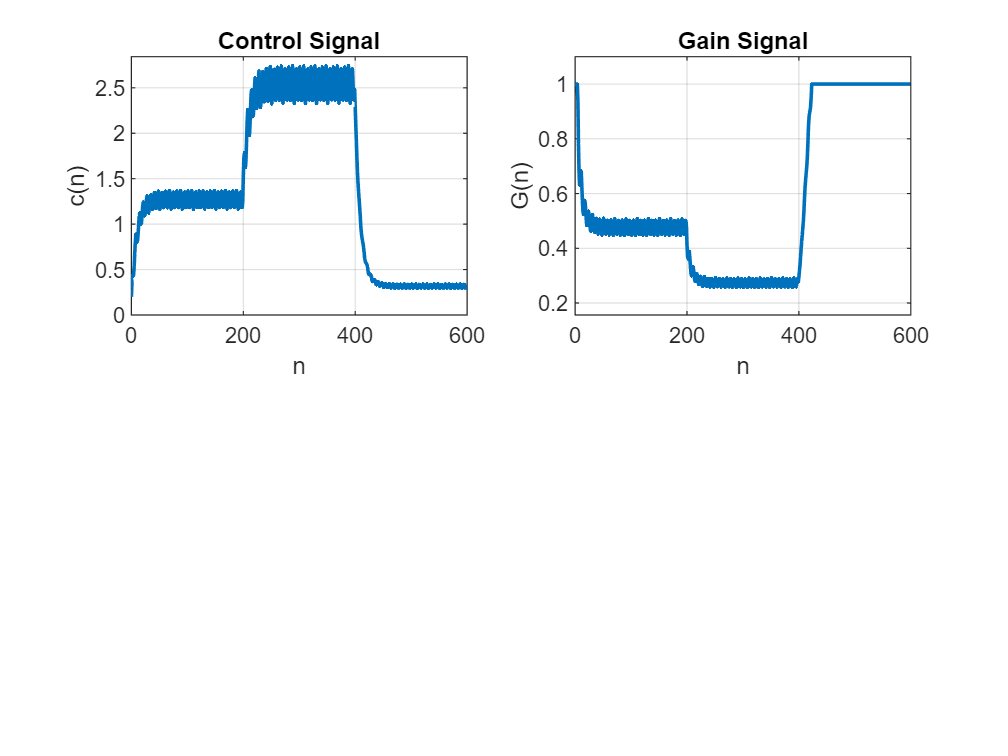

figure('Name','Control & Gain Signals');
subplot(2,2,1);
plot(n, cn, 'LineWidth',1.5);
title('Control Signal');
xlabel('n'); ylabel('c(n)');
xlim([0 600]); ylim([0 max(cn)+0.1]); 
grid on;

subplot(2,2,2);
plot(n, gn, 'LineWidth',1.5);
title('Gain Signal');
xlabel('n'); 
ylabel('G(n)');
xlim([0 600]); 
ylim([min(gn)-0.1 1.1]); 
grid on;

#### b) Smoothed compressor

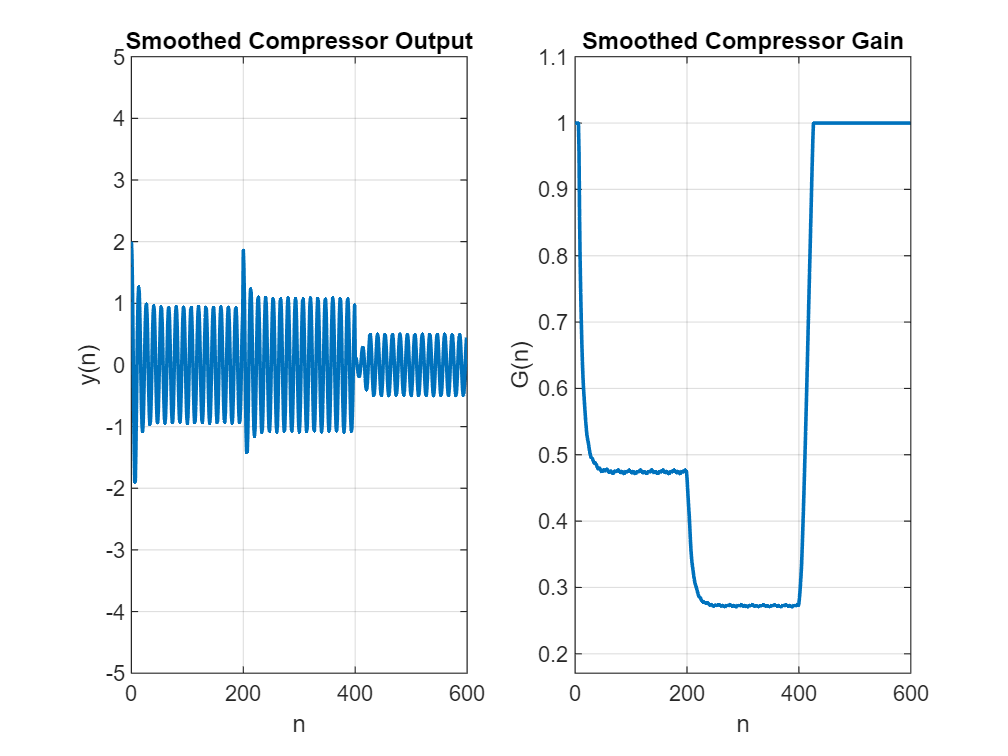

L = 7;
cn_smoothed = movmean(cn, [L - 1 0]);
gn_smoothed = ones(1, length(cn_smoothed));
gn_smoothed(cn_smoothed >= c0) = (cn_smoothed(cn_smoothed >= c0) / c0) .^ (rho - 1);

yn_smoothed = gn_smoothed .* x;

figure('Name','Smoothed Compressor Output & Gain');

subplot(1,2,1);
plot(n, yn_smoothed, 'LineWidth',1.5);
title('Smoothed Compressor Output');
xlabel('n'); 
ylabel('y(n)');
xlim([0 600]); 
ylim([-5 5]); 
grid on;

subplot(1,2,2);
plot(n, gn_smoothed, 'LineWidth',1.5);
title('Smoothed Compressor Gain');
xlabel('n'); 
ylabel('G(n)');
xlim([0 600]);
ylim([min(gn_smoothed)-0.1, max(gn_smoothed)+0.1]);
grid on;

#### c) Limiter

Control Signal

lambda = 0.9;
c0 = 1.5;
rho = 0.1;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

Gain Signal

L = 7;
cn_smoothed = movmean(cn, [L - 1 0]);
gn_smoothed = ones(1, length(cn_smoothed));
gn_smoothed(cn_smoothed >= c0) = (cn_smoothed(cn_smoothed >= c0) / c0) .^ (rho - 1);
yn_limiter = gn_smoothed .* x;

Plot Signals

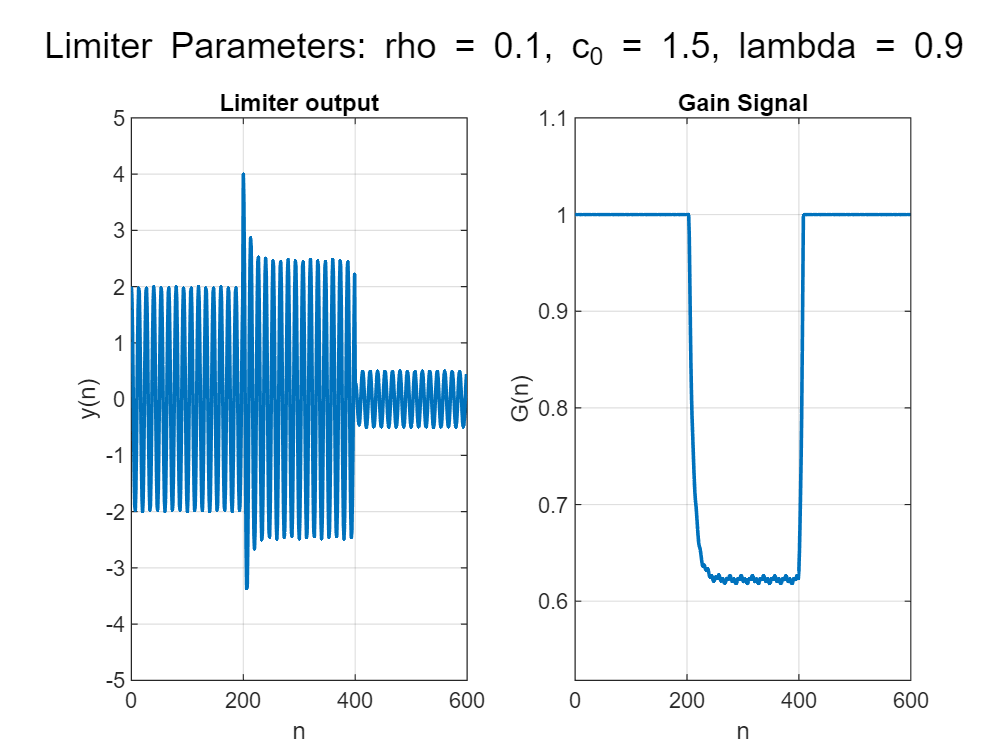

figure("Name", 'Limiter output vs Gain signal');
sgtitle('Limiter Parameters: rho = 0.1, c_0 = 1.5, lambda = 0.9');
subplot(1, 2, 1);
plot(n, yn_limiter, 'LineWidth', 1.5);
title('Limiter output');
xlabel('n');
ylabel('y(n)');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, gn_smoothed, 'LineWidth',1.5);
title('Gain Signal');
xlabel('n'); ylabel('G(n)');
xlim([0 600]); 
ylim([min(gn_smoothed)-0.1 1.1]); 
grid on;

#### d) Expander

Control Signal

lambda = 0.9;
c0 = 0.5;
rho = 2;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

Gain Signal

L = 7;
cn_smoothed = movmean(cn, [L - 1 0]);
gn_smoothed = ones(1, length(cn_smoothed));
gn_smoothed(cn_smoothed <= c0) = (cn_smoothed(cn_smoothed <= c0) / c0) .^ (rho - 1);
yn_expander = gn_smoothed .* x;

Plot Signals

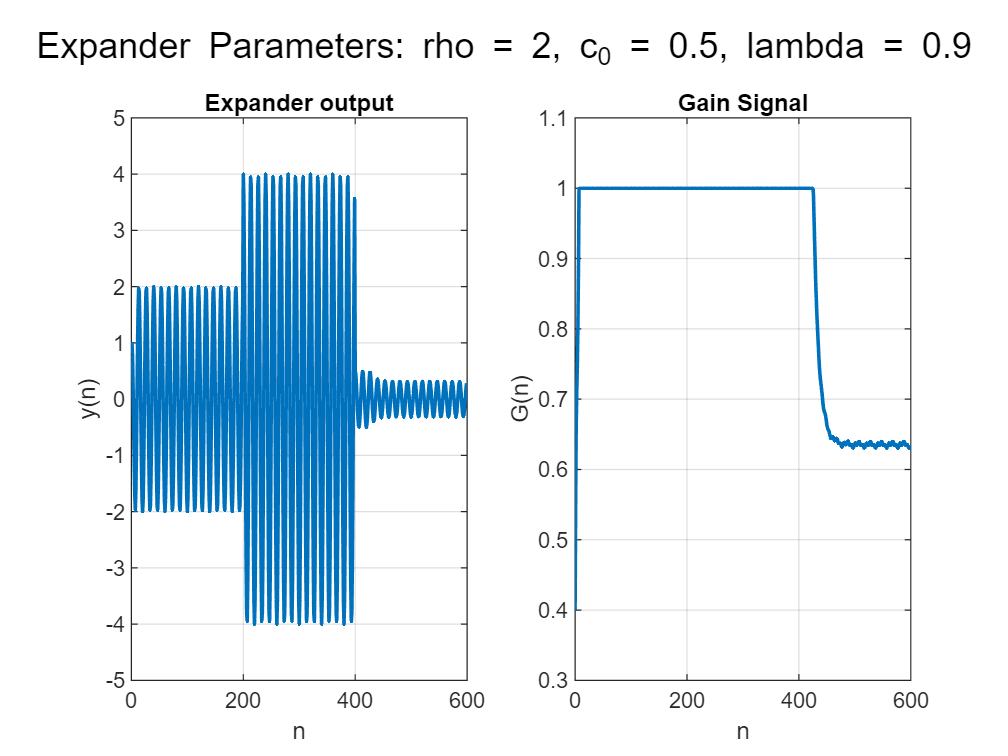

figure("Name", 'Expander output vs Gain signal');
sgtitle('Expander Parameters: rho = 2, c_0 = 0.5, lambda = 0.9');
subplot(1, 2, 1);
plot(n, yn_expander, 'LineWidth', 1.5);
title('Expander output');
xlabel('n');
ylabel('y(n)');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, gn_smoothed, 'LineWidth',1.5);
title('Gain Signal');
xlabel('n'); ylabel('G(n)');
xlim([0 600]); 
ylim([min(gn_smoothed)-0.1 1.1]); 
grid on;

#### d) Noise Gates

Control Signal

lambda = 0.9;
c0 = 0.5;
rho = 10;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

Gain Signal

L = 7;
cn_smoothed = movmean(cn, [L - 1 0]);
gn_smoothed = ones(1, length(cn_smoothed));
gn_smoothed(cn_smoothed <= c0) = (cn_smoothed(cn_smoothed <= c0) / c0) .^ (rho - 1);
yn_noise_gates = gn_smoothed .* x;

Plot Signals

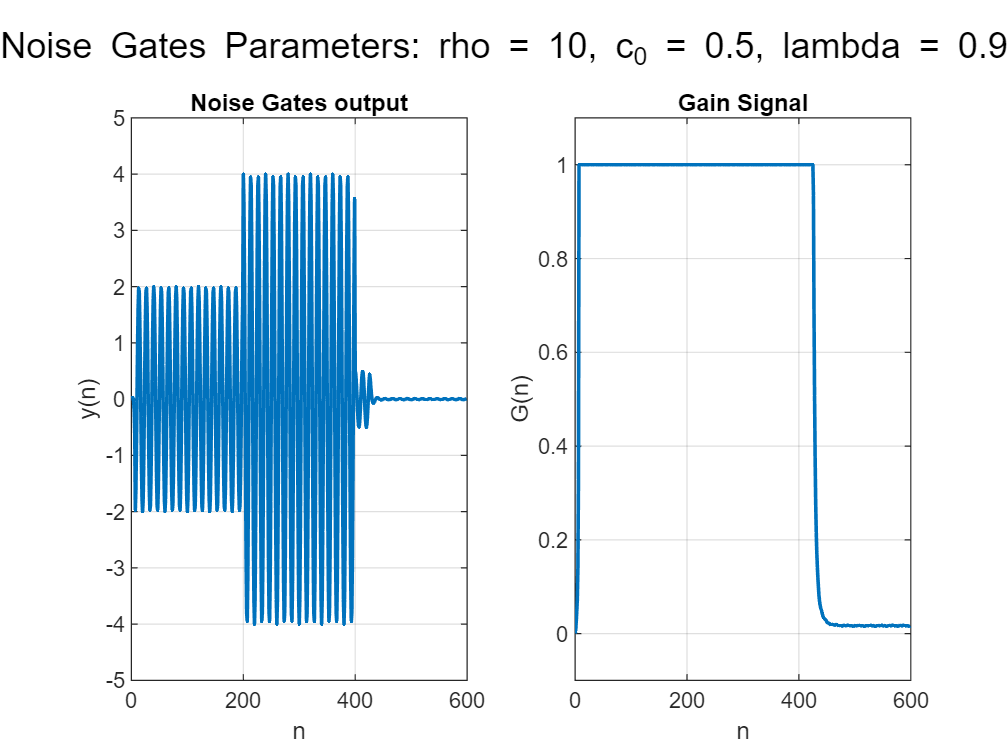

figure("Name", 'Noise Gates output vs Gain signal');
sgtitle('Noise Gates Parameters: rho = 10, c_0 = 0.5, lambda = 0.9');
subplot(1, 2, 1);
plot(n, yn_noise_gates, 'LineWidth', 1.5);
title('Noise Gates output');
xlabel('n');
ylabel('y(n)');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, gn_smoothed, 'LineWidth',1.5);
title('Gain Signal');
xlabel('n'); ylabel('G(n)');
xlim([0 600]); 
ylim([min(gn_smoothed)-0.1 1.1]); 
grid on;

### Part 3: Compressor with rho=0.25 

Control Signal

lambda = 0.9;
c0 = 0.5;
rho = 0.25;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

Gain Signal

gn     = ones(size(cn));
above  = cn >= c0;
gn(above) = (cn(above) / c0).^(rho - 1);
yn_compressor = gn .* x;

Plot Signals

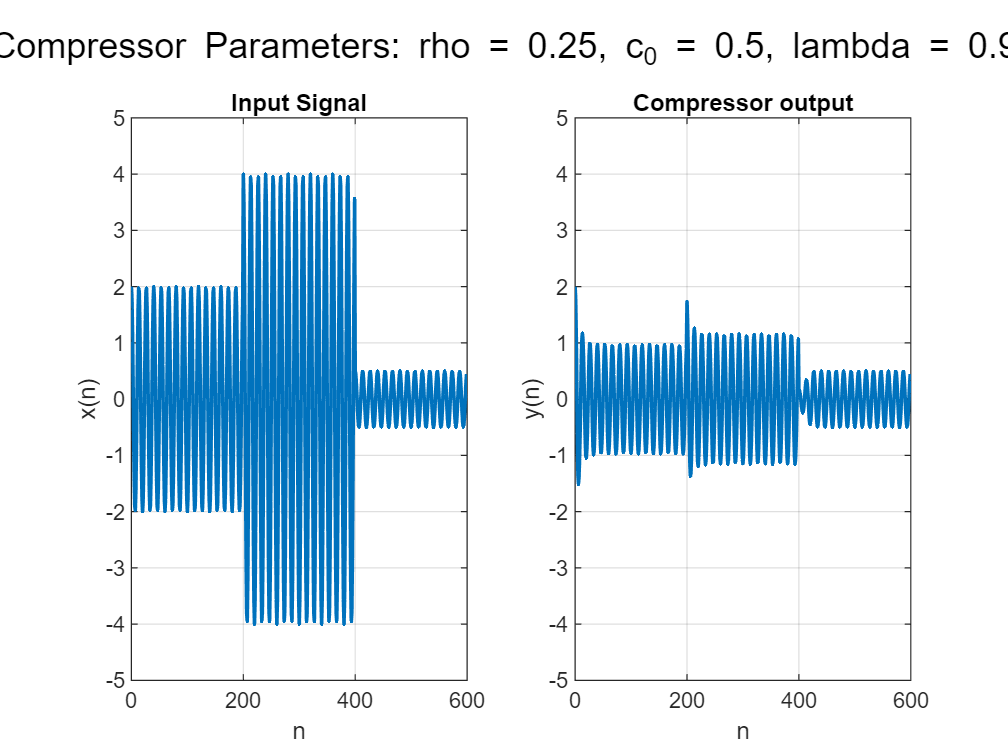

figure("Name", 'Input Signal vs Compressed Signal with rho = 0.25');
sgtitle('Compressor Parameters: rho = 0.25, c_0 = 0.5, lambda = 0.9');
subplot(1, 2, 1);
plot(n, x, 'LineWidth', 1.5);
title('Input Signal');
xlabel('n');
ylabel('x(n)');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, yn_compressor, 'LineWidth', 1.5);
title('Compressor output');
xlabel('n');
ylabel('y(n)');
xlim([0 600]);
ylim([-5 5]);
grid on;

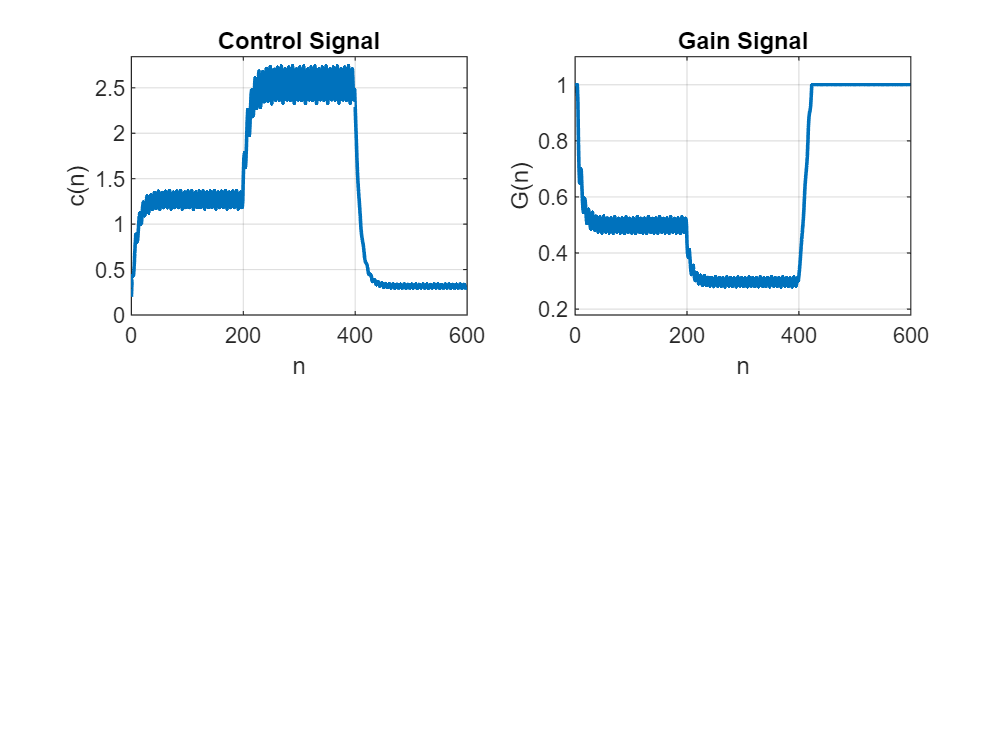

figure('Name','Control & Gain Signals with rho = 0.25');
subplot(2,2,1);
plot(n, cn, 'LineWidth',1.5);
title('Control Signal');
xlabel('n'); ylabel('c(n)');
xlim([0 600]); ylim([0 max(cn)+0.1]); 
grid on;

subplot(2,2,2);
plot(n, gn, 'LineWidth',1.5);
title('Gain Signal');
xlabel('n'); 
ylabel('G(n)');
xlim([0 600]); 
ylim([min(gn)-0.1 1.1]); 
grid on;

### Part 4: Compressor with new parameters

Control Signal

lambda = 0.9;
c0 = 1.3;
rho = 0.5;
b = 1 - lambda;
a = [1 -lambda];
cn = filter(b, a, abs(x));

Gain Signal

gn     = ones(size(cn));
above  = cn >= c0;
gn(above) = (cn(above) / c0).^(rho - 1);
yn_compressor = gn .* x;

Plot Signals

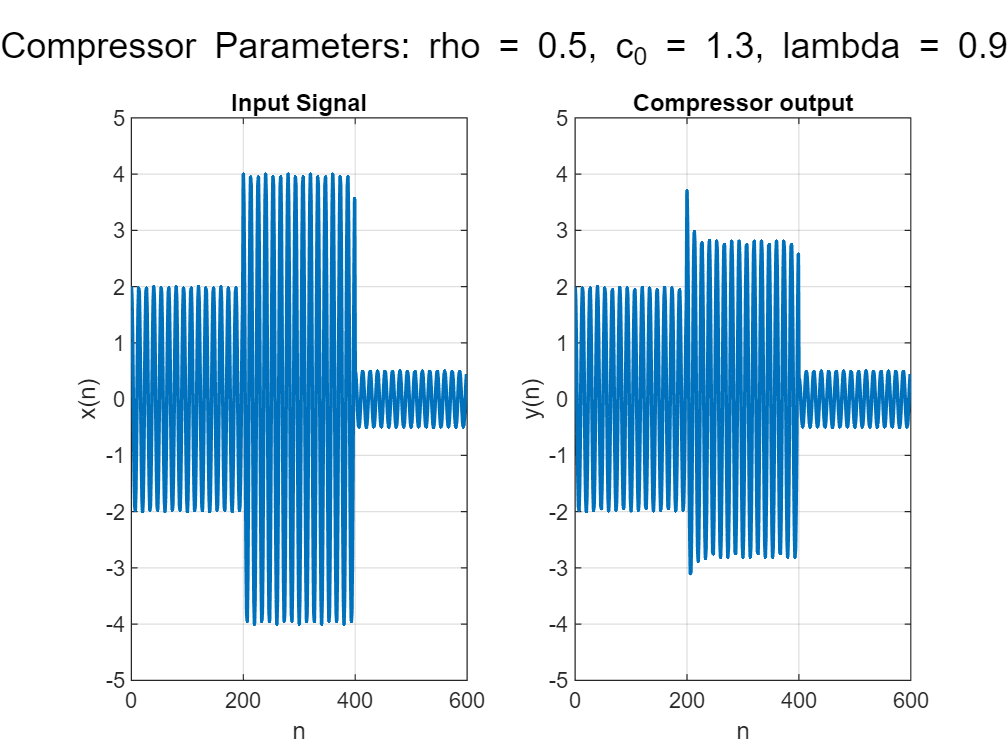

figure("Name", 'Input Signal vs Compressed Signal with new parameters');
sgtitle('Compressor Parameters: rho = 0.5, c_0 = 1.3, lambda = 0.9');
subplot(1, 2, 1);
plot(n, x, 'LineWidth', 1.5);
title('Input Signal');
xlabel('n');
ylabel('x(n)');
xlim([0 600]);
ylim([-5 5]);
grid on;
subplot(1, 2, 2);
plot(n, yn_compressor, 'LineWidth', 1.5);
title('Compressor output');
xlabel('n');
ylabel('y(n)');
xlim([0 600]);
ylim([-5 5]);
grid on;

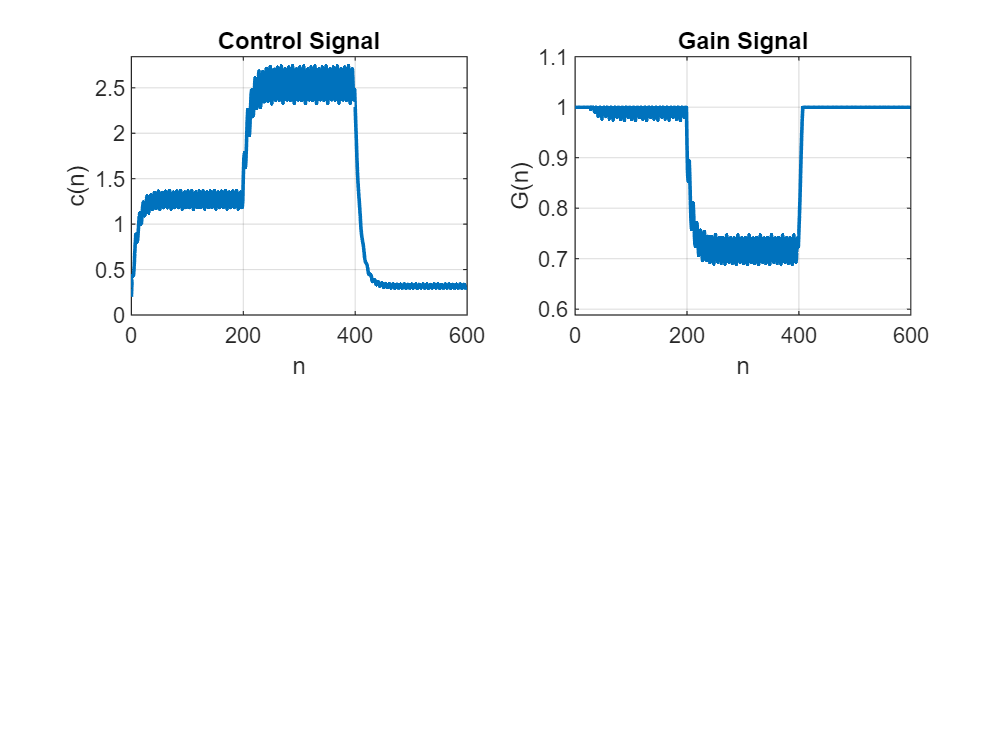

figure('Name','Control & Gain Signals with new parameters');
subplot(2,2,1);
plot(n, cn, 'LineWidth',1.5);
title('Control Signal');
xlabel('n'); ylabel('c(n)');
xlim([0 600]); ylim([0 max(cn)+0.1]); 
grid on;

subplot(2,2,2);
plot(n, gn, 'LineWidth',1.5);
title('Gain Signal');
xlabel('n'); 
ylabel('G(n)');
xlim([0 600]); 
ylim([min(gn)-0.1 1.1]); 
grid on;

With these parameters we only change the middle part because:

- Block 1 (A=2):⟨∣2cos (n)∣⟩≈2⋅(2/π)≈1.27<1.3  ⟹ **no compression**

- Block 2 (A=4):⟨∣4cos (n)∣⟩≈4⋅(2/π)≈2.55>1.3  ⟹ **compression**

- Block 3 (A=0.5):⟨∣0.5cos (n)∣⟩≈0.5⋅(2/π)≈0.32<1.3  ⟹ **no compression**